# Waste Analysis Demo

Use the ThermoeconomicModel function to make waste analysis

### **Read and create the Thermoeconomic Model**

file='gturbo_model.xlsx';
model=ThermoeconomicModel(file);

INFO: cStatusLogger. Productive Structure is valid
INFO: cStatusLogger. Format Configuration is valid
INFO: cStatusLogger. Exergy values [Reference] are valid
INFO: cStatusLogger. Exergy values [GEN97] are valid
INFO: cStatusLogger. Exergy values [T79] are valid
INFO: cStatusLogger. Exergy values [C79] are valid
INFO: cStatusLogger. Exergy values [R78] are valid
INFO: cStatusLogger. Exergy values [T50] are valid
INFO: cStatusLogger. No Resources Cost Data available
INFO: cStatusLogger. Waste definition is valid
INFO: cReadModelXLS. Data Model gturbo_model.xlsx is valid
INFO: cThermoeconomicModel. Set State: Reference
INFO: cThermoeconomicModel. Calculated Thermoeconomic Analysis for State: Reference


model.setDebug(false);

### Define waste parameters

WasteFlows=convertCharsToStrings(model.getWasteFlows);
WasteFlow=convertStringsToChars(WasteFlows(2));
model.setWasteType(WasteFlow,'RESOURCES');
model.setWasteRecycled(WasteFlow,0);

### Compute Exergy Cost

model.wasteAnalysis;

Waste Definition Table

  Id  Key  Type             Recycling (%)
------------------------------------------
   1  QI   IRREVERSIBILITY        0.00
   2  QG   RESOURCES              0.00


 Waste Allocation Table  (%)

 Key          QI        QG
---------------------------
 CMB1      31.38     49.23
 CMB2      20.97     50.77
 CMP1      20.03      0.00
 CMP2       5.25      0.00
 TRB1       6.64      0.00
 TRB2       6.04      0.00
 PHTR       9.69      0.00



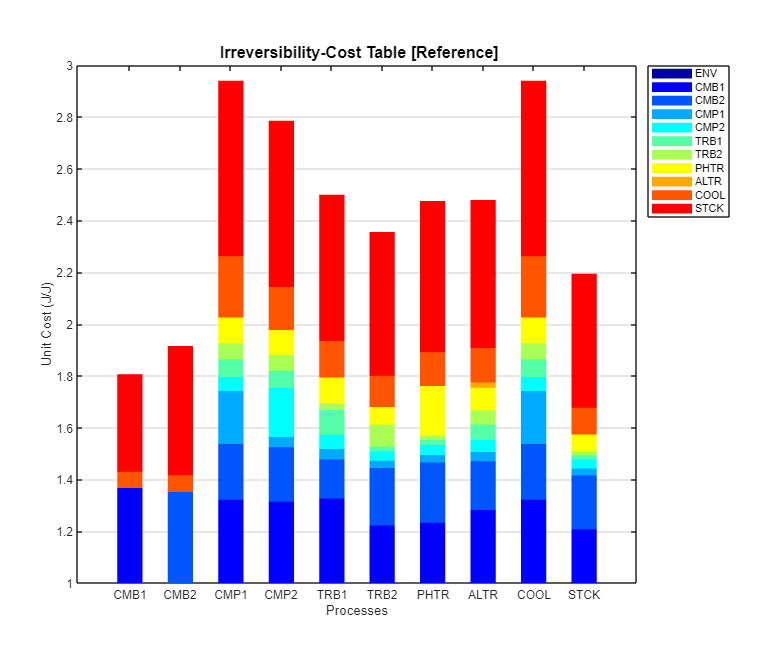

graphCost(model,cType.Graphs.PROCESS_COST);

### Recycling Analysis

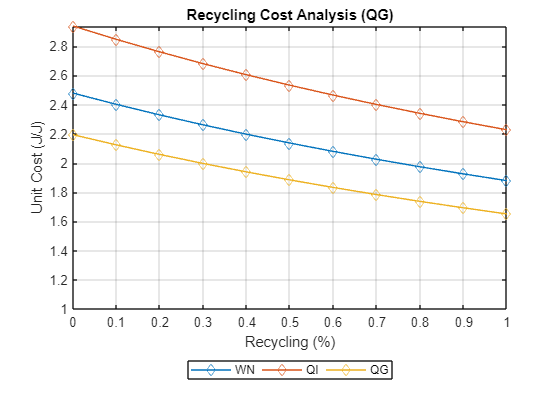

rad=model.recyclingAnalysis(WasteFlow);
rad.graphRecycling;

printResults(rad);

 Recycling Analysis (J/J)

 Recycle (%)         WN        QI        QG
--------------------------------------------
      0          2.4792    2.9388    2.1942
     10          2.4020    2.8473    2.1243
     20          2.3296    2.7615    2.0588
     30          2.2615    2.6807    1.9971
     40          2.1973    2.6047    1.9391
     50          2.1368    2.5330    1.8843
     60          2.0796    2.4652    1.8326
     70          2.0255    2.4010    1.7836
     80          1.9742    2.3402    1.7371
     90          1.9255    2.2824    1.6931
    100          1.8792    2.2275    1.6512

